# Detect Defects on Printed Circuit Boards Using YOLOX Network

This example shows how to detect, localize, and classify defects in printed circuit boards (PCBs) using a YOLOX object detector.

PCBs contain individual electronic devices and their connections. Defects in PCBs can result in poor performance or product failures. By detecting defects in PCBs, production lines can remove faulty PCBs and ensure that electronic devices are of high quality.

## Download Pretrained YOLOX Detector

By default, this example downloads a pretrained version of the YOLOX object detector [1] using the `downloadTrainedNetwork` helper function. The helper function is attached to this example as a supporting file. You can use the pretrained network to run the entire example without waiting for training to complete.

trainedPCBDefectDetectorNet_url = "https://ssd.mathworks.com/supportfiles/"+ ...
    "vision/data/trainedPCBDefectDetectorYOLOX.zip";
downloadTrainedNetwork(trainedPCBDefectDetectorNet_url,pwd);
load("trainedPCBDefectDetectorYOLOX.mat");

## Download PCB Defect Data Set

This example uses the PCB defect data set [2] [3]. The data set contains 1,386 images of PCB elements with synthesized defects. The data has six types of defect: missing hole, mouse bite, open circuit, short, spur, and spurious copper. Each image contains multiple defects of the same category in different locations. The data set contains bounding box and coordinate information for every defect in every image. The size of the data set is 1.87 GB. 

Specify `dataDir` as the location of the data set. Download the data set using the `downloadPCBDefectData` helper function. This function is attached to the example as a supporting file.

dataDir = fullfile(tempdir,"PCBDefects");
downloadPCBDefectData(dataDir)

## Perform Object Detection

Read a sample image from the dataset.

sampleImage = imread(fullfile(dataDir,"PCB-DATASET-master","images", ...
    "Open_circuit","01_open_circuit_01.jpg"));

Predict the bounding boxes, labels, and class-specific confidence scores for each bounding box by using the [`detect`](docid:vision_ref#mw_9d98b93e-317c-44dc-b403-f61f216558fb) function.

[bboxes,scores,labels] = detect(detector,sampleImage);

Display the results.

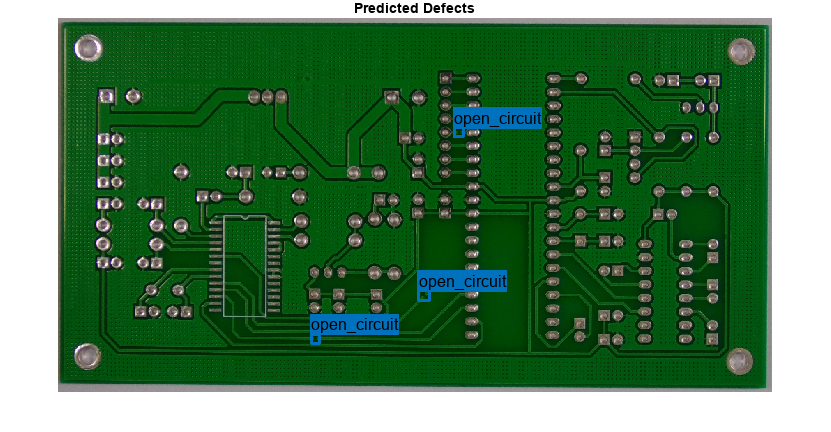

imshow(sampleImage)
showShape("rectangle",bboxes,Label=labels);
title("Predicted Defects")

## Prepare Data for Training

Create an image datastore that reads and manages the image data.

imageDir = fullfile(dataDir,"PCB-DATASET-master","images");
imds = imageDatastore(imageDir,FileExtensions=".jpg",IncludeSubfolders=true);

Create a file datastore that reads the annotation data from XML files. Specify a custom read function that parses the XML files and extracts the bounding box information. The custom read function, `readPCBDefectAnnotations`, is attached to the example as a supporting file.

annoDir = fullfile(dataDir,"PCB-DATASET-master","Annotations");
fds = fileDatastore(annoDir,ReadFcn=@readPCBDefectAnnotations, ...
    FileExtensions=".xml",IncludeSubfolders=true);

Save the labeled bounding box data as a box label datastore.

annotations = readall(fds);
tbl = struct2table(vertcat(annotations{:}));
blds = boxLabelDatastore(tbl);

Get the names of the object classes as a categorical vector.

classNames = categories(blds.LabelData{1,2})

classNames = 6×1 cell array
    {'missing_hole'   }
    {'mouse_bite'     }
    {'open_circuit'   }
    {'short'          }
    {'spur'           }
    {'spurious_copper'}


Combine the image and box label datastores.

ds = combine(imds,blds);

### Analyze Object Class Distribution

Measure the distribution of class labels in the data set by using the [`countEachLabel`](docid:vision_ref#mw_1c600e69-1a15-4538-9629-7bceaafbd4e7) function. The classes in this data set are balanced.

countEachLabel(blds)

ans = 6×3 table
         Label         Count    ImageCount
    _______________    _____    __________

    missing_hole        497        115    
    mouse_bite          492        115    
    open_circuit        482        116    
    short               491        116    
    spur                488        115    
    spurious_copper     503        116    


### Partition Data

Prior to partitioning the data, set the global random state to the default state to ensure a higher reproducibility of results.

rng("default");

Split the data set into training, validation, and test sets. Because the total number of images is relatively small, allocate a relatively large percentage (70%) of the data for training. Allocate 15% for validation and the rest for testing.

numImages = ds.numpartitions;
numTrain = floor(0.7*numImages);
numVal = floor(0.15*numImages);

shuffledIndices = randperm(numImages);
dsTrain = subset(ds,shuffledIndices(1:numTrain));
dsVal = subset(ds,shuffledIndices(numTrain+1:numTrain+numVal));
dsTest = subset(ds,shuffledIndices(numTrain+numVal+1:end));

### Augment Training Data

Augment the training data by using the [`transform`](docid:matlab_ref#mw_16489124-fe7e-4381-b715-8d3b8b30a9f6) function with custom preprocessing operations specified by the `augmentDataForPCBDefectDetection` helper function. The helper function is attached to the example as a supporting file. The `augmentDataForPCBDefectDetection` function applies these augmentations to the input data:

- Random horizontal flip (reflection)

- Random resizing by a scale factor in the range [1, 1.1]

- Random translation in the horizontal and vertical directions in the range [-50, 50] pixels

dsTrain = transform(dsTrain,@augmentDataForPCBDefectDetection);

## Define YOLOX Object Detector Network Architecture

Create the YOLOX object detector by using the [`yoloxObjectDetector`](docid:vision_ref#mw_9c6e3e1c-638f-42a5-9a77-e539221d5827) function. Specify pretrained network created using CSP-DarkNet-53 as the base network and trained on the COCO data set [1]. Specify the class names and the network input size. 

inputSize = [800 800 3];
detectorIn = yoloxObjectDetector("tiny-coco",classNames,InputSize=inputSize);

## Specify Training Options

Specify network training options using the [`trainingOptions`](docid:nnet_ref#bu59f0q) function. Train the object detector using the SGDM solver for a maximum of 100 epochs. Specify the `ValidationData` name-value argument as the validation data. Set `OutputNetwork` to `"best-validation-loss"` to obtain the network with the lowest validation loss during training when the training finishes.

options = trainingOptions("sgdm", ...
    InitialLearnRate=5e-4, ...
    LearnRateSchedule="piecewise", ...
    LearnRateDropFactor=0.99, ...
    LearnRateDropPeriod=1, ...   
    MiniBatchSize=20, ...
    MaxEpochs=100, ...
    BatchNormalizationStatistics="moving", ...
    ExecutionEnvironment="auto", ...
    Shuffle="every-epoch", ...
    VerboseFrequency=25, ...
    ValidationFrequency=100, ...
    ValidationData=dsVal, ...
    ResetInputNormalization=false, ...
    OutputNetwork="best-validation-loss", ...
    GradientThreshold=30, ...
    L2Regularization=5e-4);

## Train Detector

To train the detector, set the `doTraining` variable to `true`. Train the detector by using the [`trainYOLOXObjectDetector`](docid:vision_ref#mw_7186e994-2795-42e0-b4d4-1f38ead25988) function.

Train on one or more GPUs, if they are available. Using a GPU requires a Parallel Computing Toolbox™ license and a CUDA®-enabled NVIDIA® GPU. For more information, see [GPU Computing Requirements](docid:distcomp_ug#mw_57e04559-0b60-42d5-ad55-e77ec5f5865f). Training takes about 7.5 hours on an NVIDIA Titan RTX™ with 24 GB of memory.

doTraining = false;
if doTraining       
    [detector,info] = trainYOLOXObjectDetector(dsTrain,detectorIn,options,"FreezeSubNetwork","none");
    modelDateTime = string(datetime("now",Format="yyyy-MM-dd-HH-mm-ss"));
    save(fullfile(tempdir,"trainedPCBDefectDetectorYoloX"+modelDateTime+".mat"), ...
        "detector");
else
    load("trainedPCBDefectDetectorYOLOX.mat");
end

## Evaluate Detector

Evaluate the trained object detector by measuring the average precision. Precision quantifies the ability of the detector to classify objects correctly.

Detect the bounding boxes for all test images.

detectionResults = detect(detector,dsTest);

Calculate the average precision score for each class by using the [`evaluateObjectDetection`](docid:vision_ref#mw_6aecf450-1718-4e91-b2cf-2972f639a177) function. Also calculate the recall and precision values for the detection of each defect object. Recall quantifies the ability of the detector to detect all relevant objects for a class.

metrics = evaluateObjectDetection(detectionResults,dsTest);
precision = metrics.ClassMetrics.Precision;
recall = metrics.ClassMetrics.Recall;
averagePrecision = cell2mat(metrics.ClassMetrics.AP);

Display the average precision score for each class.

classNames = replace(classNames,"_"," ");
table(classNames,averagePrecision)

ans = 6×2 table
        classNames         averagePrecision
    ___________________    ________________

    {'missing hole'   }        0.98092     
    {'mouse bite'     }        0.84501     
    {'open circuit'   }        0.91325     
    {'short'          }        0.97348     
    {'spur'           }        0.90091     
    {'spurious copper'}        0.84583     


A precision-recall (PR) curve highlights how precise a detector is at varying levels of recall. The ideal precision is 1 at all recall levels. Plot the PR curve for the test data.

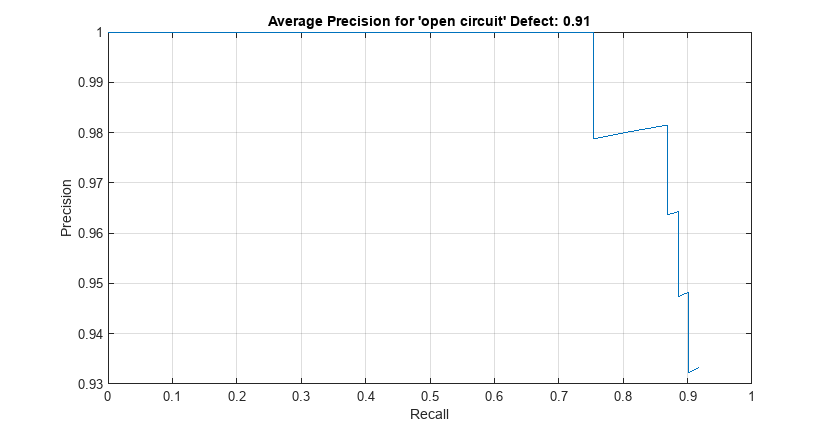

class = 3;
plot(recall{class},precision{class})
title(sprintf("Average Precision for '" + classNames(class) + "' Defect: " + "%.2f",averagePrecision(class)))
xlabel("Recall")
ylabel("Precision")
grid on

### Evaluate Object Size-based Detection Metrics

Investigate the impact of object size on detector performance with the [`metricsByArea`](docid:vision_ref#mw_5f58ce21-e10a-47de-81ba-6ea576c4b2c6) function, which computes the object detection metrics for specific object size ranges. To evaluate size-based metrics, you can define the object size ranges based on a custom set of ranges. First, break the test image bounding box sizes into small, medium, and large object size categories according to percentile boundaries of the 33rd and 66th percentile of the test set object area distribution. 

Plot the test set object size distribution, where the bounding box area defines the object size.

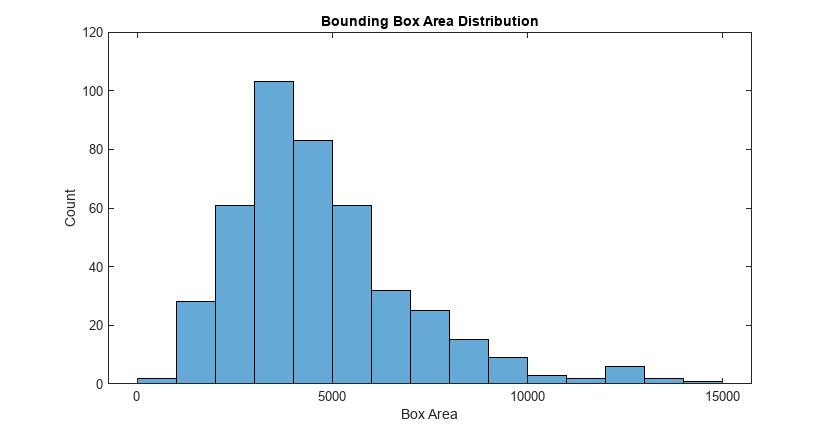

testSetObjects = dsTest.UnderlyingDatastores{2};
objectLabels = readall(testSetObjects);
boxes = objectLabels(:,1);
boxes = vertcat(boxes{:});
boxArea = prod(boxes(:,3:4),2);
histogram(boxArea)
title("Bounding Box Area Distribution")
xlabel("Box Area");
ylabel("Count")

Define the bounding box area ranges, and then evaluate object detection metrics for the defined area ranges using `metricsByArea`. The mean average precision (mAP) metric of the trained detector performs approximately the same across small, medium, and large object sizes, with a slight performance improvement for medium objects.

boxPrctileBoundaries = prctile(boxArea,100*[1/3,2/3]);
metricsByArea(metrics,[0, boxPrctileBoundaries, inf])

ans = 3×4 table
       AreaRange        NumObjects      mAP          AP    
    ________________    __________    _______    __________

         0    3573.7       144        0.82447    {[0.8245]}
    3573.7      5107       145        0.93077    {[0.9308]}
      5107       Inf       144        0.87555    {[0.8756]}


## References

[1] Ge, Zheng, Songtao Liu, Feng Wang, Zeming Li, and Jian Sun. "YOLOX: Exceeding YOLO Series in 2021", arXiv, August 6, 2021. [https://arxiv.org/abs/2107.08430](https://arxiv.org/abs/2107.08430).

[2] Huang, Weibo, and Peng Wei. "A PCB Dataset for Defects Detection and Classification." Preprint, submitted January 23, 2019. [https://arxiv.org/abs/1901.08204](https://arxiv.org/abs/1901.08204).

[3] PCB-DATASET. Accessed December 20, 2022. [https://github.com/Ironbrotherstyle/PCB-DATASET](https://github.com/Ironbrotherstyle/PCB-DATASET).

*Copyright 2023 The MathWorks, Inc.*